# Lab 1 Notebook

## 1. Normal Distributions, Integrals, and Probabilities

### A. The Normal Distribution

A normal distribution a set of data points which is centered around the mean value. It is symmetric, with mean ($\mu$) = median = mode, and is often called a "Gaussian distribution" or a "bell curve" due to its shape, as seen to the right.

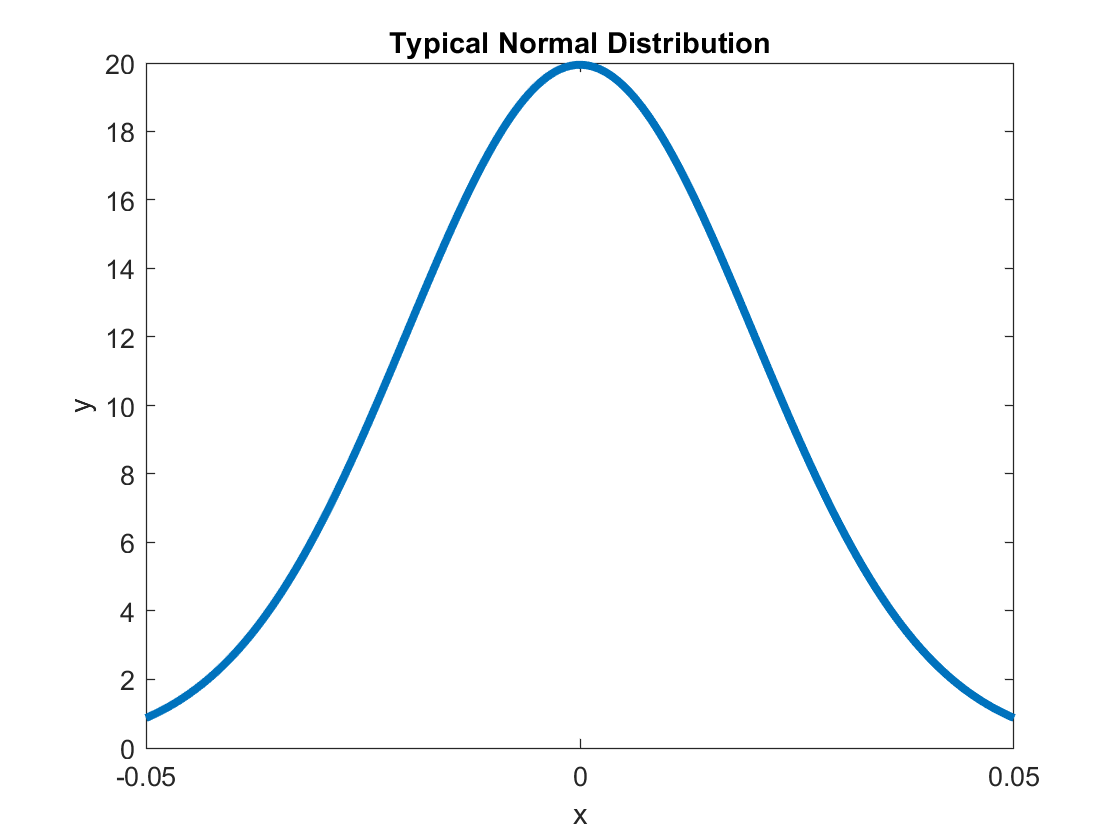

x = linspace(-0.05,0.05,1000);
bellcurve = makedist("Normal","mu",0.,"sigma",0.02);
plot(x,pdf(bellcurve,x),"LineWidth",3)

title('Typical Normal Distribution')
xlabel('x')
ylabel('y')

One numerical value associated with a normal distribution is the standard deviation, represented by $\sigma$. Standard deviation is a measure of the spread of the data, for instance a smaller standard deviation results in a thinner, higher peak whereas a larger standard deviation indicates a wider, more spread out set of data points. 

Generally, 68% of values are within one standard deviation of the mean, 95% of values are within two standard deviations, and 99.7% of values are within three standard deviations. 

#### The Standard Normal Distribution

In a standard normal distribution, which is a particular subset of normal distributions, $\mu =0$ and $\sigma =1$. 

#### Mathematical Representation

Typical probability density function: 


$$f\left(x\right)=\frac{1}{\sigma \sqrt{2\pi }}e^{-\frac{x-\mu }{2\sigma^2 }}$$


Standard normal probablility density function:


$$p\left(x\right)=\frac{1}{\sqrt{2\pi }}e^{-\frac{x^2 }{2}}$$


Note that the factor $\frac{1}{\sqrt{2\pi }}$ lets the integral from negative infinity to positive infinity be 1, effectively normalizing the data and allowing the function to give a probability. Taking the integral of f on the interval [a,b] gives the probability of a data point being in that section of the distribution. 

### B. Integrating the Standard Normal Distribution

Below are examples of finding probabilities by integrating normal distributions of various sigmas.

- Standard normal: $\mu =0$, $\sigma =1$

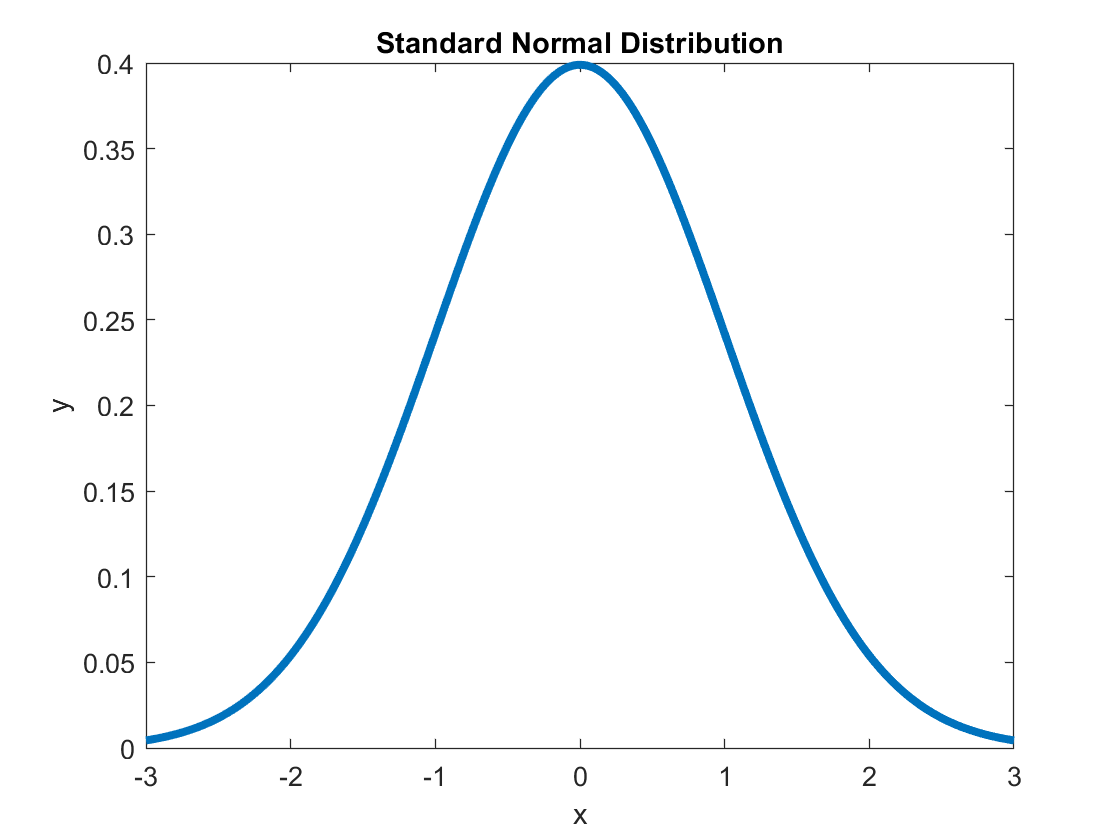

x2 = linspace(-3,3,1000);
bellcurve2 = makedist("Normal","mu",0.,"sigma",1);
plot(x2,pdf(bellcurve2,x2),"LineWidth",3)

title('Standard Normal Distribution')
xlabel('x')
ylabel('y')


p_a = normcdf(-1.5)

p_a = 0.0668


p_b = normcdf(1.5)

p_b = 0.9332


c = [-1,1];
prob_c = normcdf(c);
p_c = prob_c(2)-prob_c(1)

p_c = 0.6827

Note: these values match the values found in z-tables, which give values for probability at certain points along x. For instance, in the z-table, the probability at 1.5 is 0.93319. 

           2. $\mu =0$, $\sigma =0\ldotp 5$

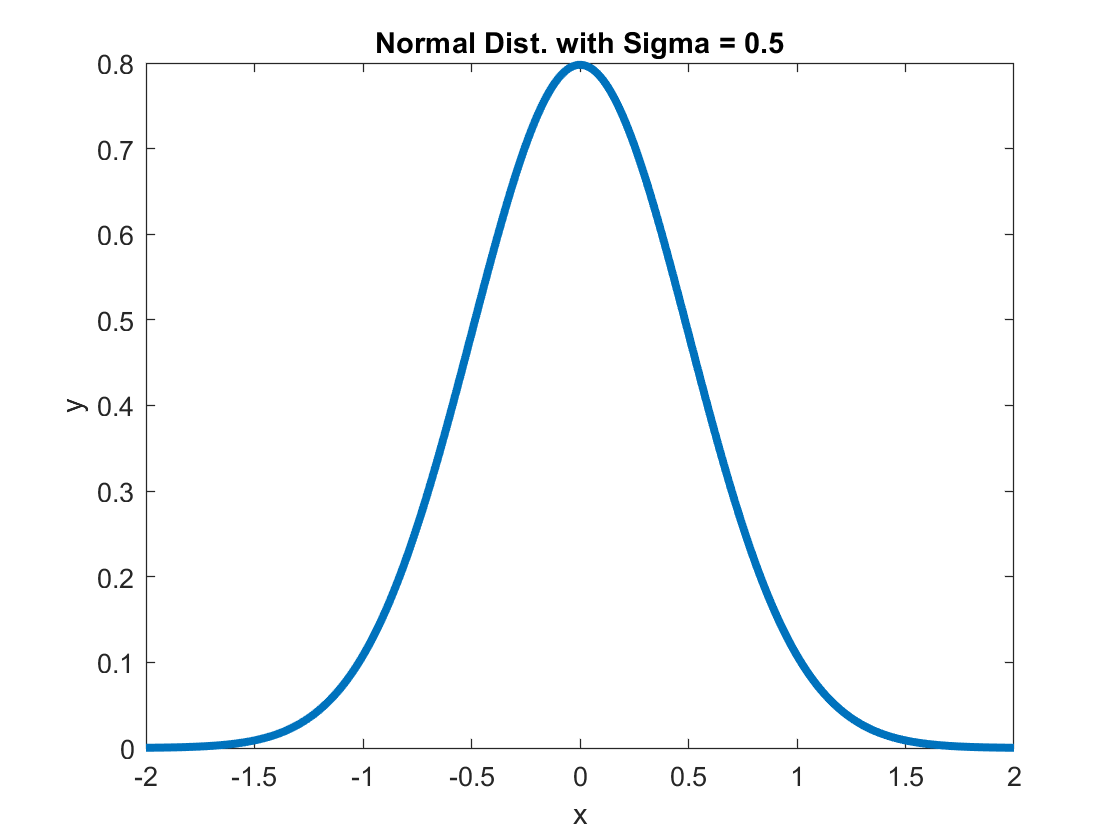

x3 = linspace(-2,2,1000);
bellcurve3 = makedist("Normal","mu",0.,"sigma",0.5);
plot(x3,pdf(bellcurve3,x3),"LineWidth",3)

title('Normal Dist. with Sigma = 0.5')
xlabel('x')
ylabel('y')


p_d = normcdf(-1.5,0,0.5)

p_d = 0.0013


p_e = normcdf(1.5,0,0.5)

p_e = 0.9987


p_f = normcdf(1,0,0.5) - normcdf(-1,0,0.5)

p_f = 0.9545

            3. $\mu =0$, $\sigma =2$

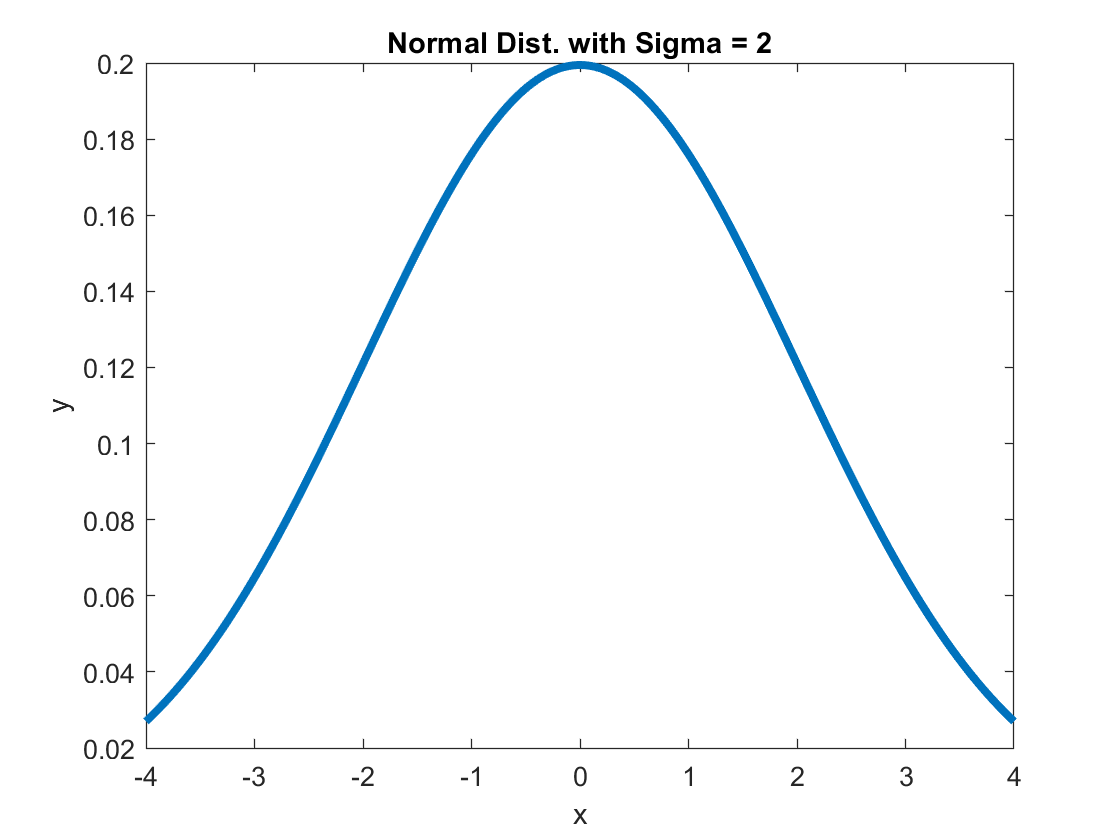

x4 = linspace(-4,4,1000);
bellcurve4 = makedist("Normal","mu",0.,"sigma",2);
plot(x4,pdf(bellcurve4,x4),"LineWidth",3)

title('Normal Dist. with Sigma = 2')
xlabel('x')
ylabel('y')


p_g = normcdf(-1.5,0,2)

p_g = 0.2266


p_h = normcdf(1.5,0,2)

p_h = 0.7734


p_i = normcdf(1,0,2) - normcdf(-1,0,2)

p_i = 0.3829

The various graphs show how $\sigma$ affects the spread of the graph, and the probabilities listed below give values for the intervals

- (-infinity, -1.5)

- (-infinity, 1.5)

- (-1,1)

for all three sigmas. 

### C. 'Sigmas'

In physics, 'sigma,' $\sigma$, can also refer to a probability. For any distribution, the probability of the background giving a data point that looks as or more signal-like than the actual reading is equal to the probability as if the data was Gaussian and the point in question was $X\sigma$ away from the mean. In this context, $\sigma$ is shorthand for probability. 

Below are several examples of finding the $\sigma$ for various probabilities. In these example, I use norminv(p), which uses a standard normal distribution ($\mu =0$, $\sigma =1$). 

The expected values are: 

p_1 = 2.7*10^-7; $5\sigma$

p_2 = 0.003; $3\sigma$

p_1 = 2.7*10^(-7);
xsigma_1 = norminv(p_1)

xsigma_1 = -5.0115


p_2 = 0.003;
xsigma_2 = norminv(p_2)

xsigma_2 = -2.7478

Clearly, the sigma values are more accurate with a smaller input probability, but for both p_1 and p_2, norminv returned a value close to the predicted sigma value. 

### D. Negative 'Sigma' 

As you can see in my example above, the probabilities I used returned a negative sigma value. I believe this is a consequence of the way norminv calculates the sigma value; it likely integrates from right to left, so small probabilities (<50%) like the ones in my example would be on the "negative" side of the distribution, resulting in a negative sigma. The negative is less important than the absolute value, which tells you how far away from the mean the data point would appear on a Gaussian distribution. For instance, I could take p_3 = 1 - p_2 and determine its $\sigma$:

p_3 = 1-p_1;
xsigma_3 = norminv(p_3)

xsigma_3 = 5.0115

The absolute value of $\sigma$ is the same for p_1 and p_3, so they are equally far away from the mean. The negative indicates only which side of the distribution the data point is placed. 

## 2. Other Continuous Analytic Distributions

d = raylrnd(0.5,1,100000);

### A. Rayleigh Distribution

The Rayleigh distribution is characterized by the probability density function $f\left(x,\sigma \right)=\frac{x}{\sigma^2 }e^{-\frac{x^2 }{2\sigma^2 }} \;\;|x\ge 0$. Sigma in this context is the scale parameter, which is directly proportional to the spread of the distribution. 

The mean of the Rayleigh distribution $\mu =\sigma^2 \sqrt{\frac{\pi }{2}}$.

### B. Plotting a Rayleigh Distrubution

The graph of a Rayleigh distribution is characterized by a tall, skewed peak with a tail, as shown below. The sharpness of the peak and tail are determined by $\sigma$. 

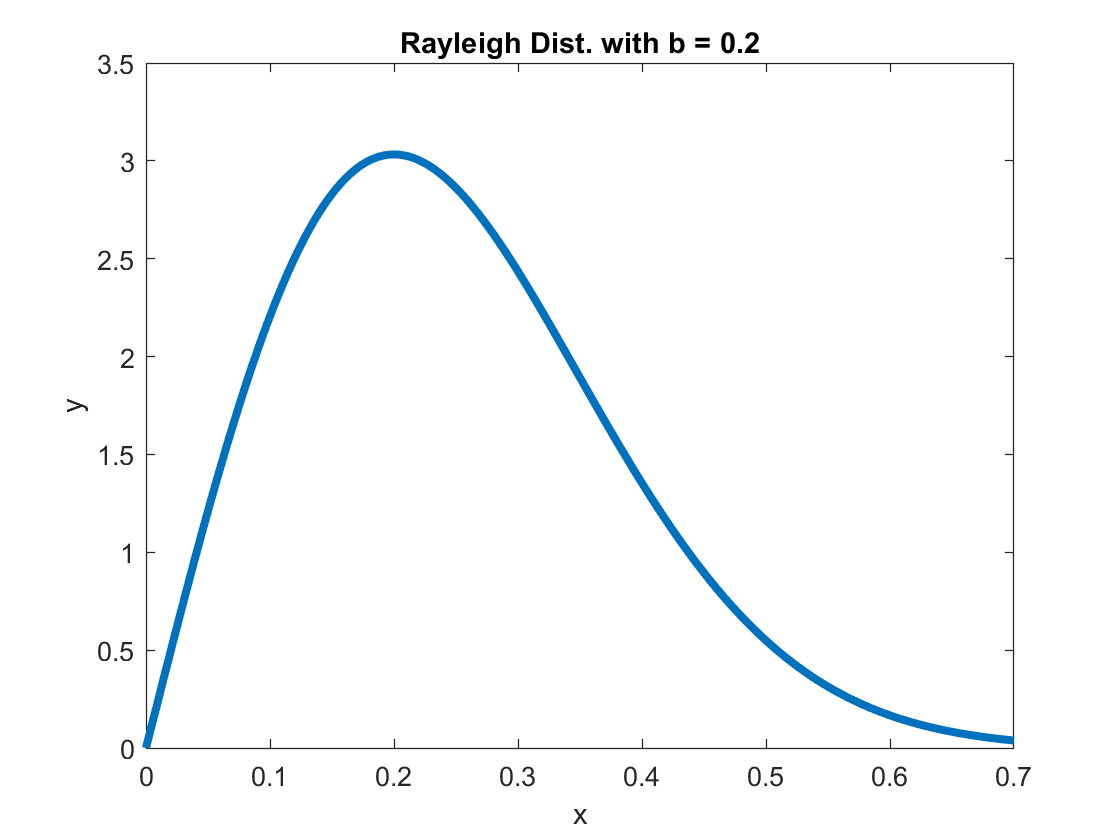

x_5 = linspace(0,0.7,1000);
rayleigh = makedist("Rayleigh",'b',0.2);
plot(x_5,pdf(rayleigh,x_5),"LineWidth",3)

title('Rayleigh Dist. with b = 0.2')
xlabel('x')
ylabel('y')

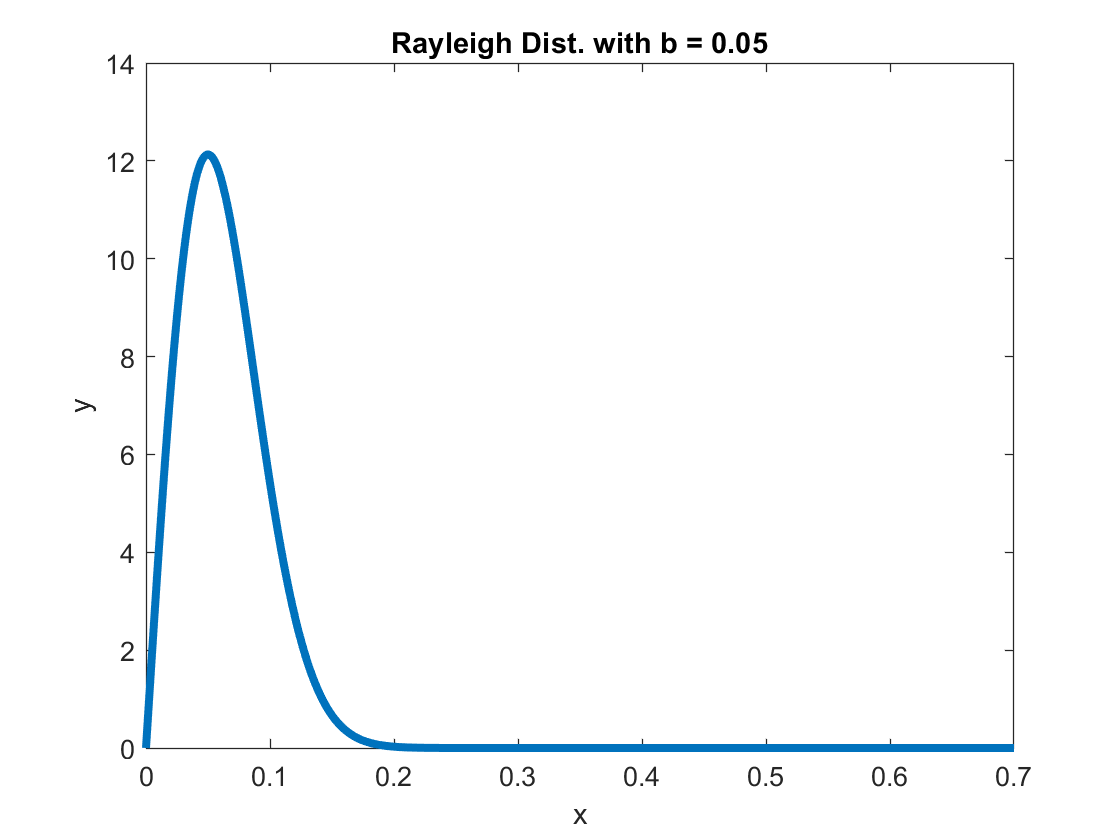


x_6 = linspace(0,0.7,1000);
rayleigh_2 = makedist("Rayleigh",'b',0.05);
plot(x_6,pdf(rayleigh_2,x_6),"LineWidth",3)

title('Rayleigh Dist. with b = 0.05')
xlabel('x')
ylabel('y')

As you can see, the larger 'b', or $\sigma$, results in a more spread out, softer peak. 

Now for a histogram from the random set of data points d that I generated at the start of section (2):

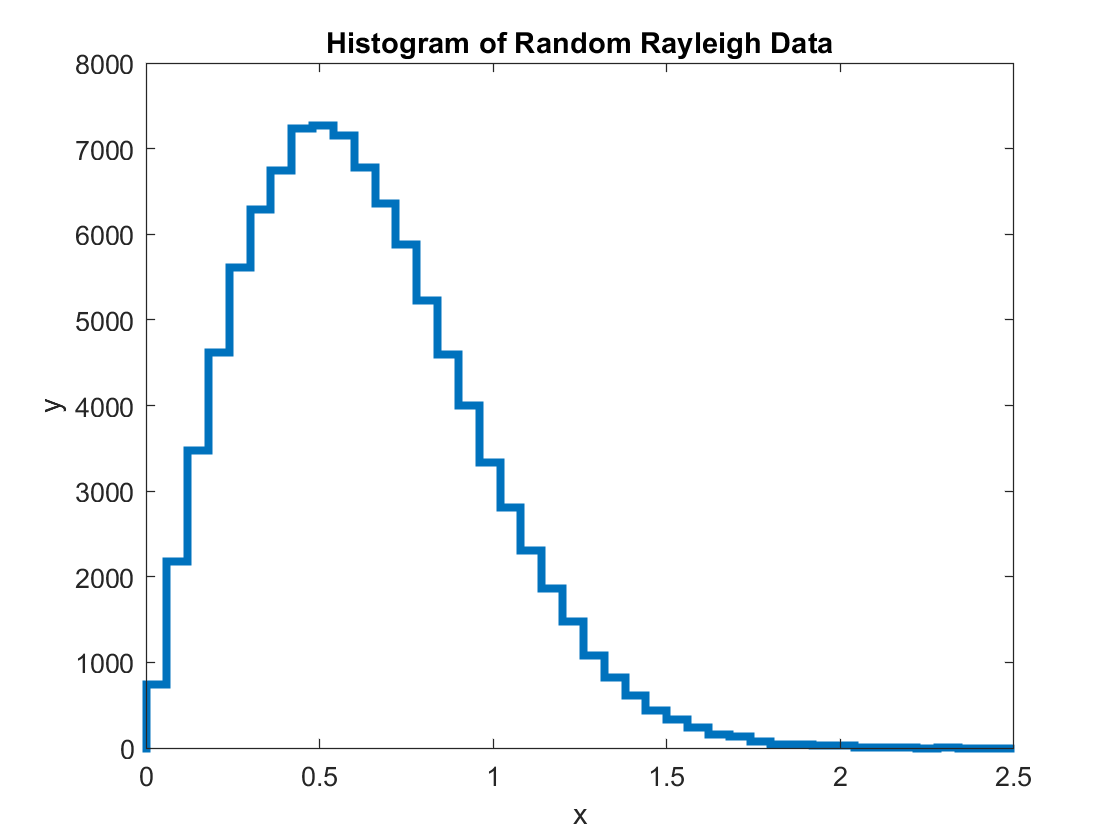

histogram(d,50,'DisplayStyle',"stairs",'Linewidth',3)
xlim([0,2.5])

title('Histogram of Random Rayleigh Data')
xlabel('x')
ylabel('y')


histogram(d,50,'DisplayStyle',"stairs",'Linewidth',3,"Normalization","pdf")
hold on
x_7 = linspace(0,2.5,1000);
pd = makedist("Rayleigh","b",0.5);
plot(x_7,pdf(pd,x_7),"Linewidth",2);
set(gca, 'YScale','log')

xlim([-0.12 2.50])
ylim([0.00 10.00])
title('Semi-Log Histogram with Overlay')
xlabel('x')
ylabel('log(y)')

## 3. Determining 'Sigma' for Some Chosen Value in My Distribution

### A. What's my value?

My hypothetical measurement value is (2.4, 12)

### B. 'The Question,' in Words

How likely is it that the background at my point of measurement gives me a data point that is as or more signal-like than my measurement?

### C. Conversion of 'The Question' into an Integral

To convert my question into a mathematical expression, I need to find the probability from my point of interest to $\infty$, so I need to integrate over my Rayleigh distribution from [2.4,$\infty$). 


$$p=\int_{2\ldotp 4}^{\infty } \frac{x}{\sigma^2 }e^{-\frac{x^2 }{2\sigma^2 }} \mathrm{dx}$$


### D. Calculating the Probability


$$p=\int_{2\ldotp 4}^{\infty } \frac{x}{\sigma^2 }e^{-\frac{x^2 }{2\sigma^2 }} \mathrm{dx}=\frac{1}{\sigma^2 }\int_{2\ldotp 4}^{\infty } xe^{-\frac{x^2 }{2\sigma^2 }} \mathrm{dx}=\frac{1}{\sigma^2 }{\left\lbrack {-\sigma }^2 e^{-\frac{x^2 }{\sigma^2 }} \right\rbrack }_{2\ldotp 4}^{\infty } =e^{-\frac{2\ldotp 4^2 }{\sigma^2 }}$$


$\sigma =0\ldotp 5$, so that evaluates to:


$$p=9\ldotp 86\cdot {10}^{-11}$$
 

### E. What's the Sigma?

Now I know my probability, I can use the process from section (1C) to find sigma:

P = 9.86*10^-11;
sigma = norminv(P)

sigma = -6.3635

So I am $6\ldotp 4\sigma$ away from the mean if my distribution were Gaussian. 

## 4. A Bit of Experimentation

Try various hypothetical measurement values and see how the probabilities and 'sigmas' change. Discuss the patterns that you see.

# Non-Continuous Distributions

## 1. The Binomial Distribution

### A. Description of the Binomial Distribution

A binomial distribution is a discrete distribution determined by parameters n and p. n is the number of independent trials/experiments and p is the normalized discrete probability distribution of the number of successes. The out come of each experiment can be success or failure -- there are only two outcomes (thus "bi" nomial). 

A good example of an experiment modelled by a binomial distribution is a coin toss; the outcome is either heads or tails and the experiment can be repeated any discrete n number of times. 

The function below describes the probability of achieving k 'successes' over the course of n trials:

$f\left(k,n,p\right)=\left\lbrack \begin{array}{c}
n\\
k
\end{array}\right\rbrack p^k {\left(1-p\right)}^{n-k}$ where the binomial coefficient $\left\lbrack \begin{array}{c}
n\\
k
\end{array}\right\rbrack =\frac{n!}{k!\left(n-k\right)!}$.

Note that $\sum_{k=1}^n f\left(k,n,p\right)=1$ since f describes a probability. 

The mean $\mu =n\cdot p$ and variance $\sigma^2 =n\cdot p\left(1-p\right)$.

### B. Example Plots

The following plots are examples of binomial distributions given varying n's and p's. 

- Classic coin toss example; n = 30, p = 0.5

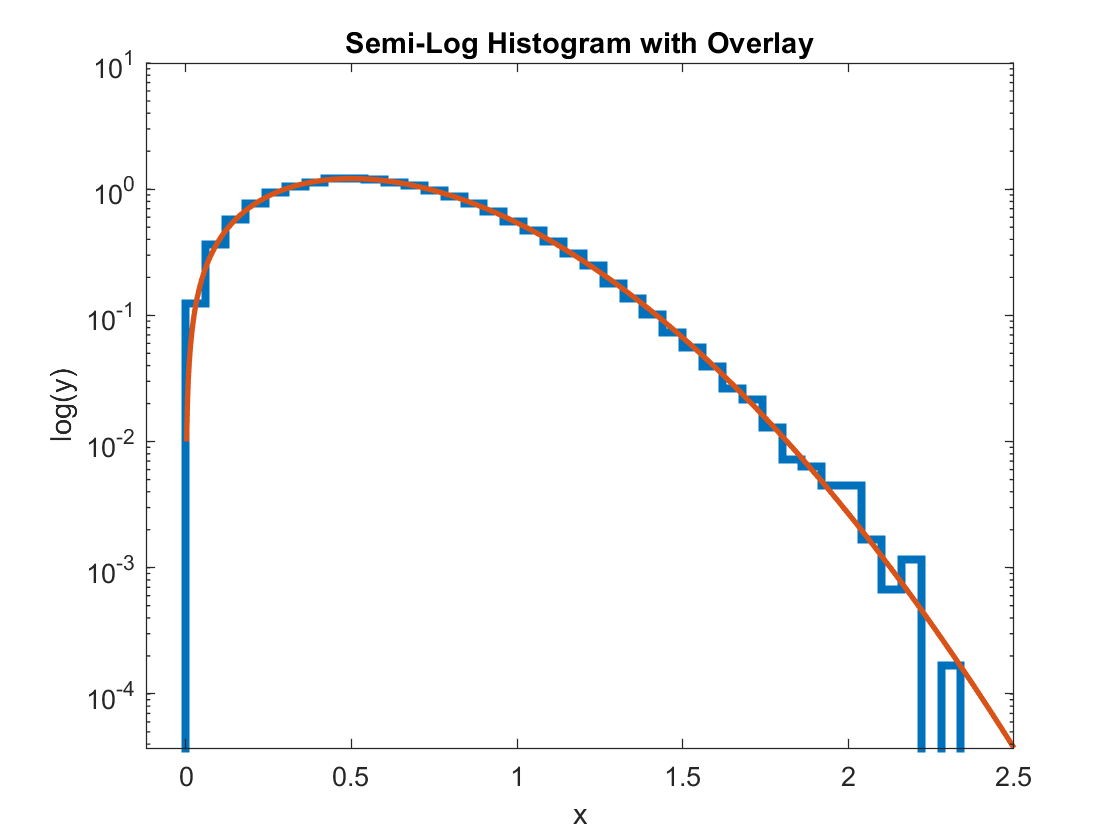

hold off

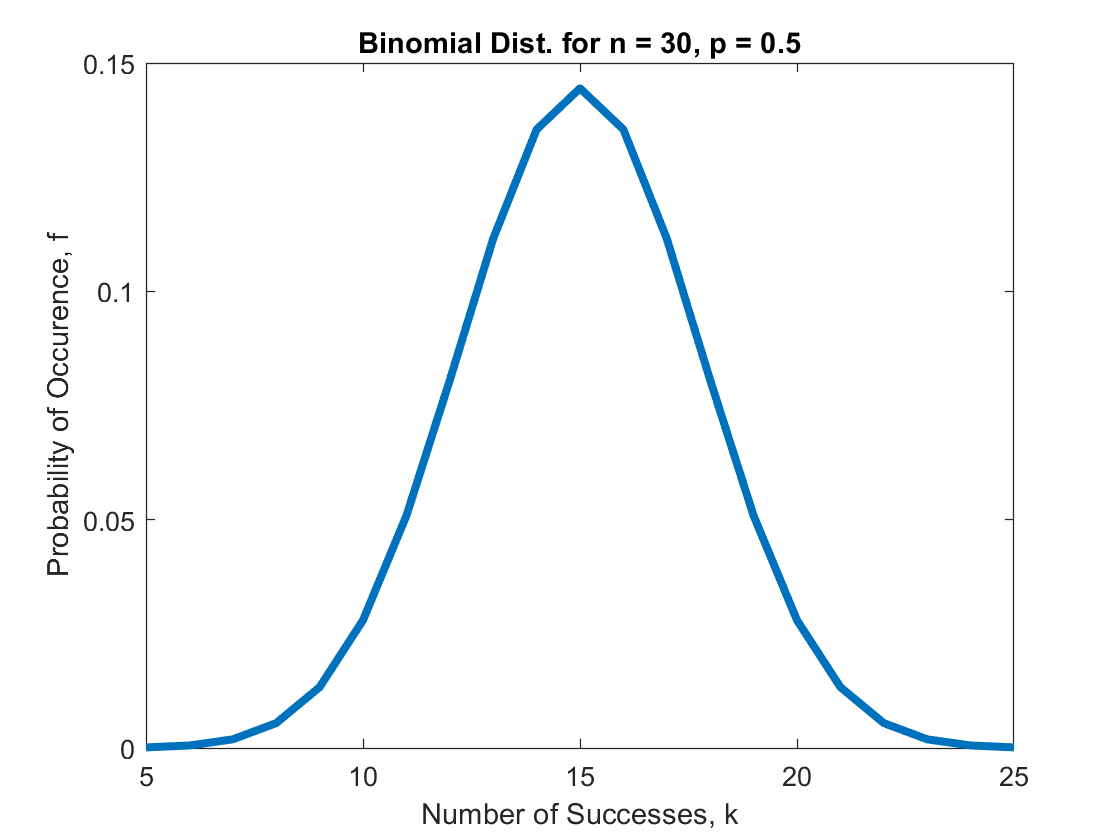

kvals = 5:1:25;
binom_1 = makedist('Binomial','N',30,'p',0.5);
plot(kvals,pdf(binom_1,kvals),"LineWidth",3)

title('Binomial Dist. for n = 30, p = 0.5')
xlabel('Number of Successes, k')
ylabel('Probability of Occurence, f')

The binomial distribution looks quite a bit like a normal distribution; if I make my step size a bit smaller:

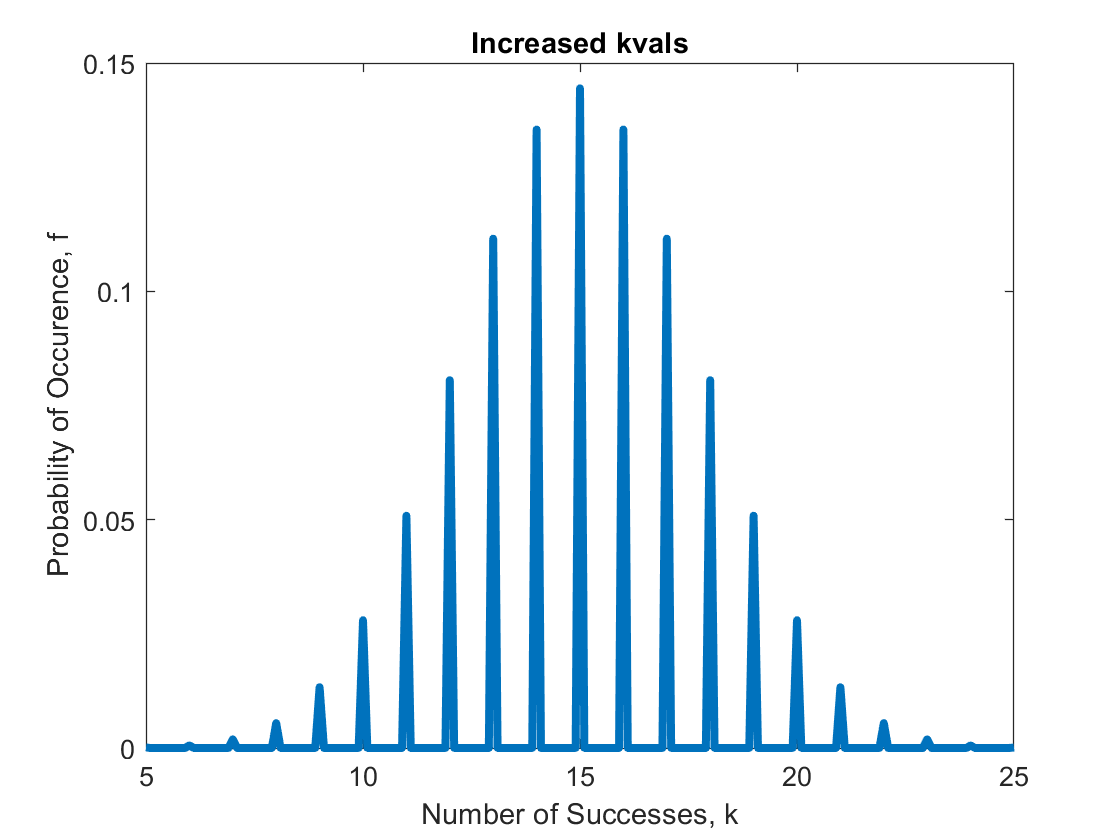

kvals_2 = 5:0.1:25;
binom_2 = makedist('Binomial','N',30,'p',0.5);
plot(kvals_2,pdf(binom_2,kvals_2),"LineWidth",3)

title('Increased kvals')
xlabel('Number of Successes, k')
ylabel('Probability of Occurence, f')

 Notice that all of the nonzero values on the graph are located at discrete intervals every whole number. 

The mean value for this distribution is $\mu =n\cdot p=30\cdot 0\ldotp 5=15$, which is where the distribution's peak is located. 

            2. n = 30, p = 0.2

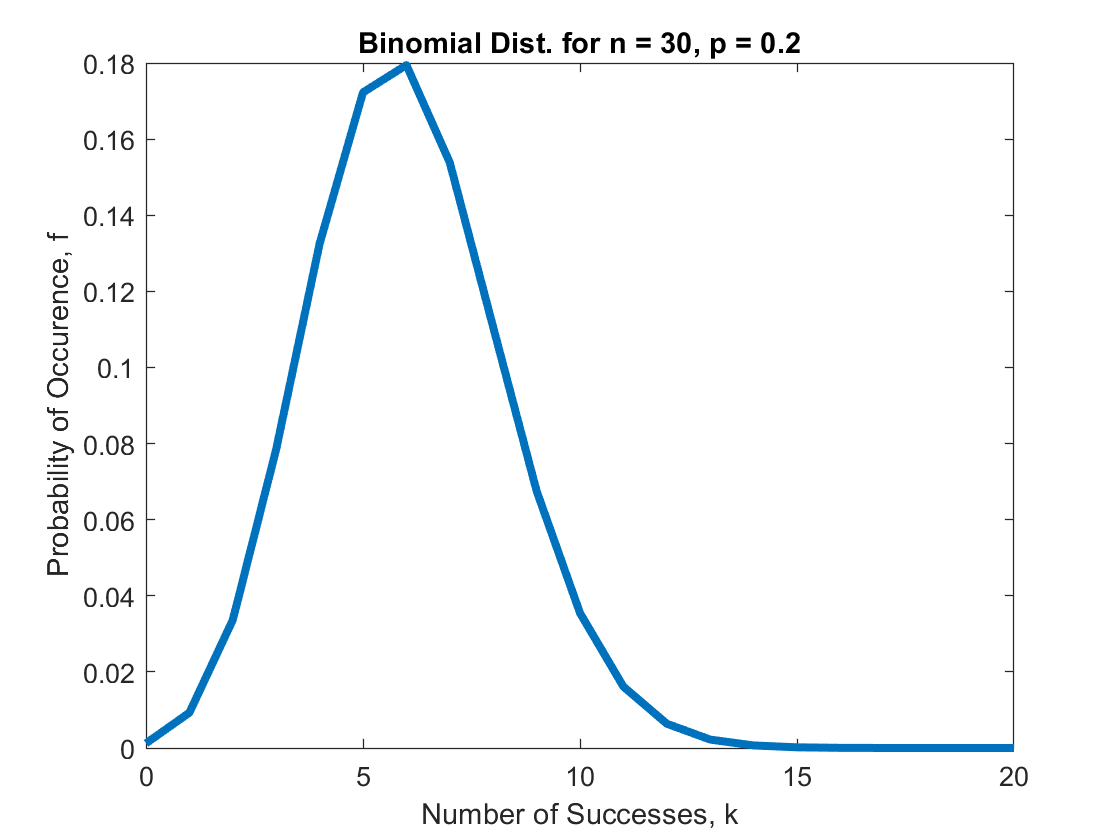

kvals_3 = 0:1:20;
binom_3 = makedist('Binomial','N',30,'p',0.2);
plot(kvals_3,pdf(binom_3,kvals_3),"LineWidth",3)

title('Binomial Dist. for n = 30, p = 0.2')
xlabel('Number of Successes, k')
ylabel('Probability of Occurence, f')

This distribution is less uniform than the previous, and is centered further to the right than (1). The mean is $\mu =30\cdot 0\ldotp 2=6$, again near the peak. 

The mean, n*p, determines where the distribution peaks. 

            3. n = 100; p = 0.5

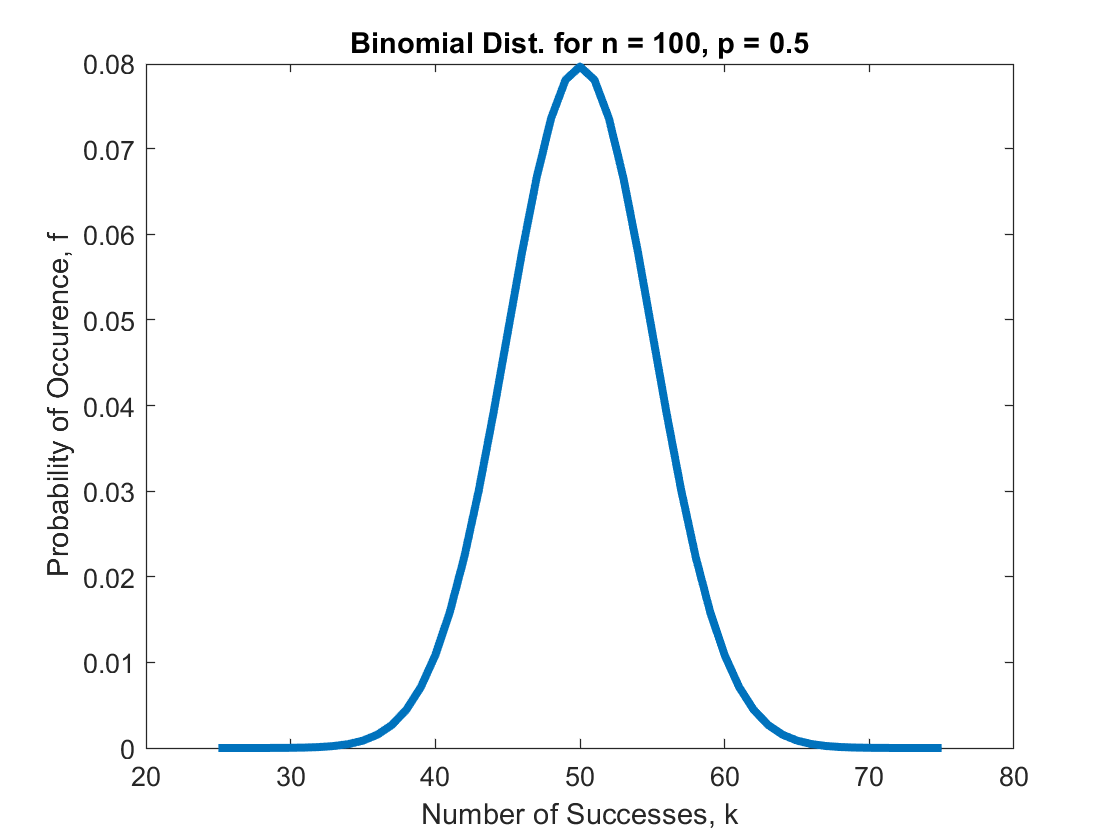

kvals_4 = 25:1:75;
binom_4 = makedist('Binomial','N',100,'p',0.5);
plot(kvals_4,pdf(binom_4,kvals_4),"LineWidth",3)

title('Binomial Dist. for n = 100, p = 0.5')
xlabel('Number of Successes, k')
ylabel('Probability of Occurence, f')

This distribution is actually wider and shorter than the n = 30, p = 0.5 distribution. Variance, $\sigma^2 =n\cdot p\left(1-p\right)$is directly proportional to n, so distributions with more trials are more spread out. For this distribution, $\sigma^2 =25,$ as opposed to (1)'s $\sigma^2 =7\ldotp 5$. 

### C. 'The Question,' II, and Corresponding Probability

### D. Discrete Probabilities and 'Sigmas'

### E. Discussion: Non-Discrete Mean

Even though the distributions are discrete, parameters like the mean and the variance are not necessarily discrete. This logically makes sense, since averages are not necessarily whole numbers. 

For example, if you have a set of three whole numbers: {5, 4, 7} and take their average, avg = 5.33, which is not discrete. 

Additionally, one basic parameter of the binomial distribution, p, is a continuous value. p can be any number between 0 and 1. Both the mean and the variance of the distribution depend on p, so naturally they are not discrete values. 

The parameters n and k, however, are discrete and $\ge$ 0. 

- Again define a hypothetical question (clearly stated), and calculate the corresponding probability

- Because the distributions are discrete, so are the probabilities and 'sigmas'. Think about this and discuss the implications for experiments.